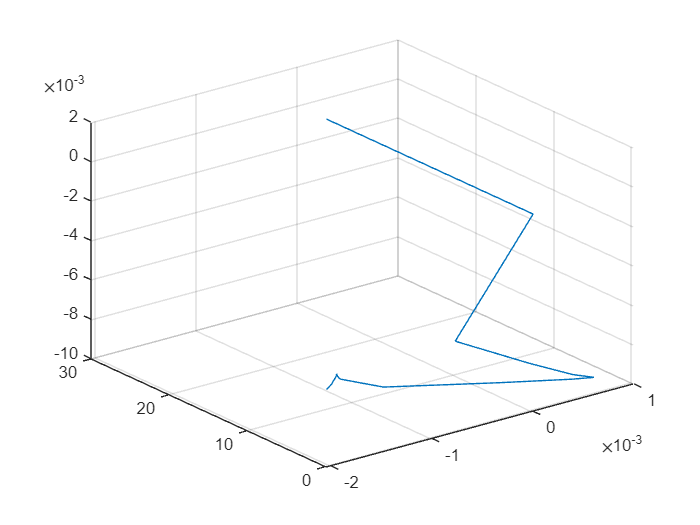

%Plot Altitude vs. Time for phase 1 and 2 (indices should be adjusted to

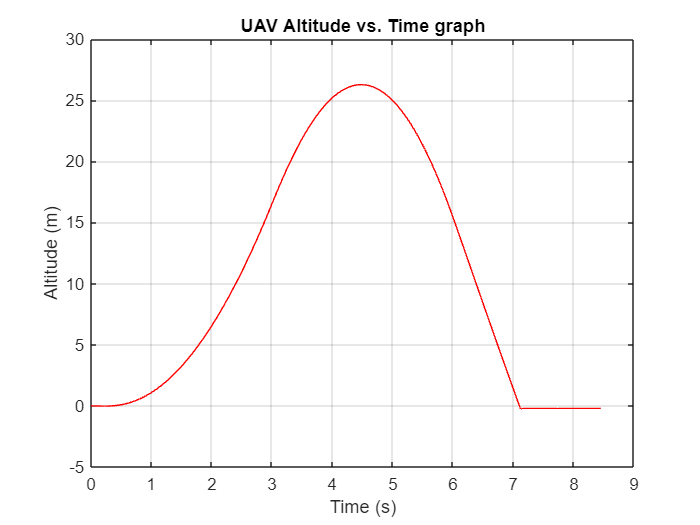

%remove extra data points after the flight if any
plot(Time(1:floor(length(Time)-18),:), PositionY(1:floor(length(PositionY)-18),:),'r');
xlabel('Time (s)');
ylabel('Altitude (m)')
title('UAV Altitude vs. Time graph')
grid on;

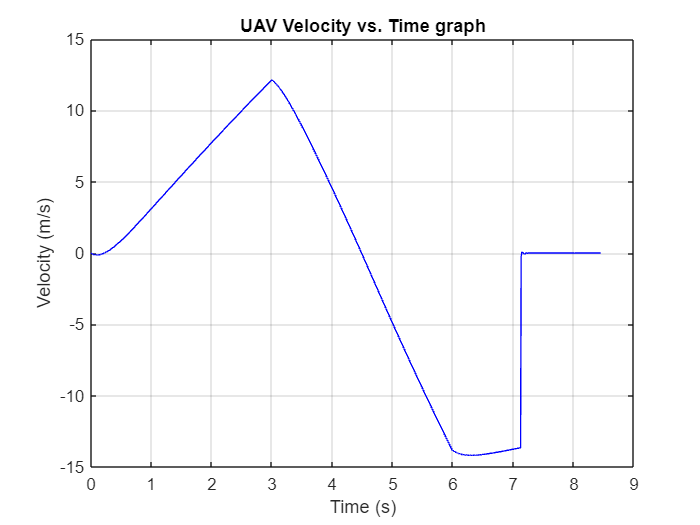


%Plot Velocity in y-axis vs. Time for phase 1 and 2 (indices should be adjusted to
%remove extra data points after the flight if any
plot(Time(1:length(Time)-18,:), VelocityY(1:length(VelocityY)-18,:), 'b');
xlabel('Time (s)');
ylabel('Velocity (m/s)')
title('UAV Velocity vs. Time graph')
grid on;

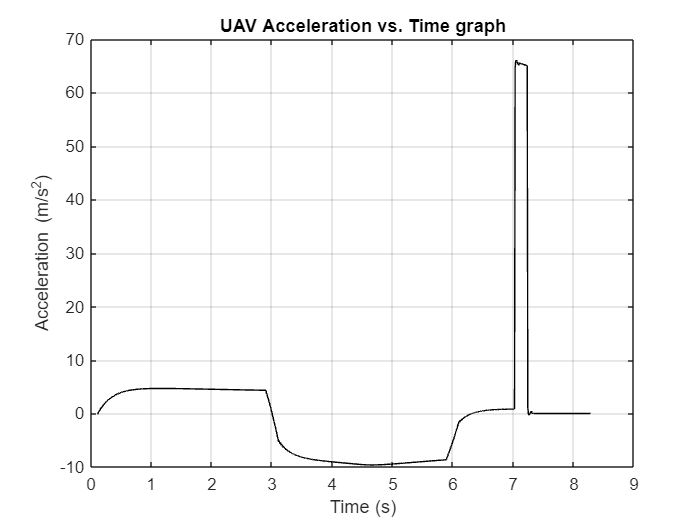


%Ca;culate acceleration by differentiating the velocity data
g = 9.81;
Timestep = 0.01;
AccY = zeros(length(VelocityY),1);
for j = 1:length(VelocityY)
    if j == 1
        AccY(j,1) = NaN;
    else
        AccY(j,1) = (VelocityY(j,1)- VelocityY(j-1,1))/Timestep;
    end
end

%Moving average
data1 = AccY;
windowSize = 20;
n = length(data1);
movingAverage_1 = zeros(1, n);

for i = 1:n
    % Define the window range
    startIdx = max(1, i - floor(windowSize / 2));
    endIdx = min(n, i + floor(windowSize / 2));

    % Compute the average
    movingAverage_1(i) = mean(data1(startIdx:endIdx));
end

windowSize = 20;
n = length(Time);
movingAverage_Time = zeros(1, n);

for i = 1:n
    % Define the window range
    startIdx = max(1, i - floor(windowSize / 2));
    endIdx = min(n, i + floor(windowSize / 2));

    % Compute the average
    movingAverage_Time(i) = mean(Time(startIdx:endIdx));
end

%Plot Acceleration (m/s^2) vs. Time for phase 1 and 2 (indices should be adjusted to
%remove extra data points after the flight if any
plot(movingAverage_Time(:,1:length(movingAverage_Time)-35), movingAverage_1(:,1:length(movingAverage_1)-35),'k')
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)')
title('UAV Acceleration vs. Time graph')
grid on;

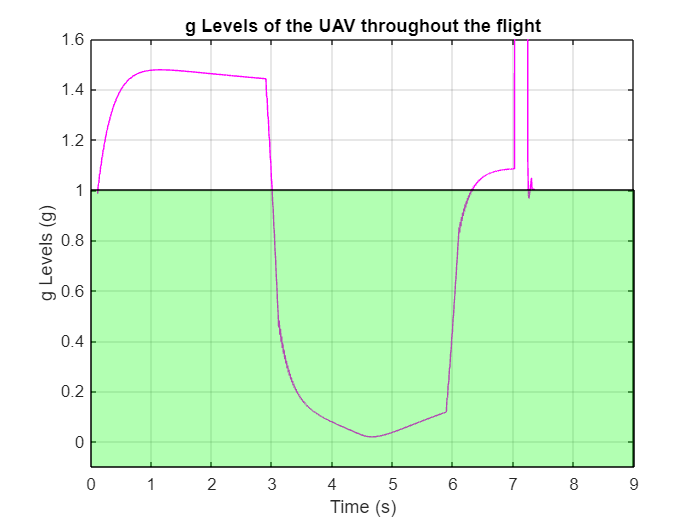



%Plot Acceleration (g) vs. Time for phase 1 and 2 (indices should be adjusted to
%remove extra data points after the flight if any
plot(movingAverage_Time(:,1:length(movingAverage_Time)-35),(movingAverage_1(:,1:length(movingAverage_1)-35) + 9.81)/(9.81),'m')
xlabel('Time (s)');
ylabel('g Levels (g)');
title('g Levels of the UAV throughout the flight')
grid on;

%marking the microgravity regions
x = [0 ceil(movingAverage_Time(length(movingAverage_Time))) ceil(movingAverage_Time(length(movingAverage_Time))) 0];
y = [-0.1 -0.1 1 1];
patch(x,y,'g','FaceAlpha',0.3);
xlim([0 4])
ylim([-0.1 1.6])

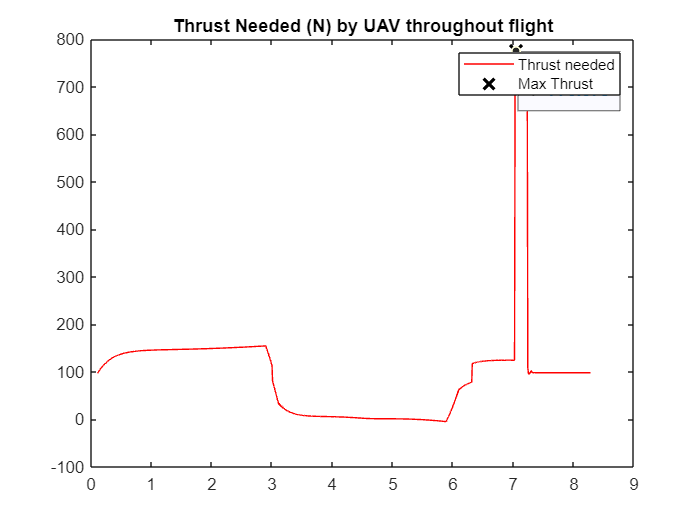


%Calculate thrust
Thrust = ones(n, 1);
Drag = ones(n, 1);
F_net = ones(n, 1);

%ADJUST MASS
UAVmass = 10; %kg

for i = 1:n
    Drag(i,1) = - (movingAverage_1(i)/abs(movingAverage_1(i)))*0.5*VelocityY(i,1)^2*1.225*0.15*1.05;
    F_net(i,1) = UAVmass*movingAverage_1(i);
    Weight = -g*UAVmass;
    Thrust(i,1) = F_net(i,1)-Weight-Drag(i,1);
end
[maxThrust, I] = max(Thrust(1:length(movingAverage_Time)-35,:));

%Plot thrust vs. time
plot(movingAverage_Time(:,1:length(movingAverage_Time)-35),Thrust(1:length(movingAverage_Time)-35,:),'r');
hold on;
%Plot max. thrust point
plot(movingAverage_Time(I), maxThrust,'kx','MarkerSize',10,'LineWidth',2);
hold off;
title('Thrust Needed (N) by UAV throughout flight');
legend('Thrust needed', 'Max Thrust');

ax = gca;
chart = ax.Children(1);
datatip(chart,movingAverage_Time(I), maxThrust);

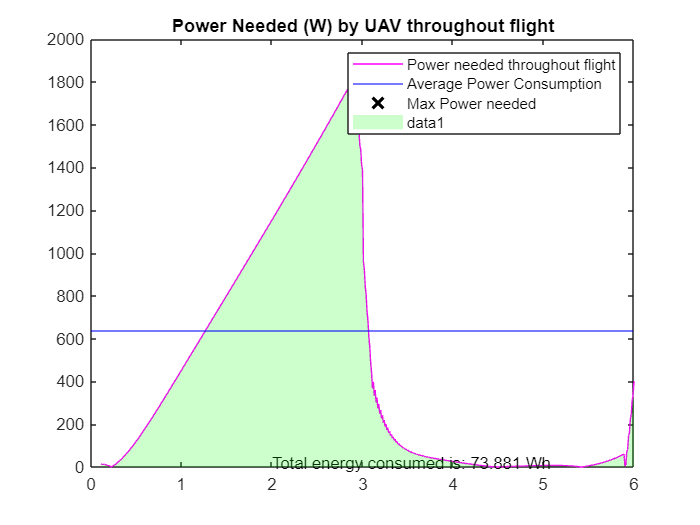


%PCalculating Power consumed
Power = ones(n,1);
for i = 1:n
    Power(i,1) = abs(Thrust(i,1)*VelocityY(i,1));
end

%Plotting power consumed
plot(movingAverage_Time(:,1:length(movingAverage_Time)-35),(Power(1:length(movingAverage_Time)-35,:)),'m')
%Calculate and plot average power consumption and peak power consumption
avgPower = mean((Power(1:length(movingAverage_Time)-35,:)),'omitnan');
[maxPower, I1] = max(Power(1:length(movingAverage_Time)-35,:));
hold on;
yline(avgPower,'b');
plot(movingAverage_Time(I1), maxPower,'kx','MarkerSize',10,'LineWidth',2)
% ylim([0 200])
xlim([0 6])
ax = gca;
chart = ax.Children(1);
datatip(chart,movingAverage_Time(I1), maxPower);

title('Power Needed (W) by UAV throughout flight');
legend('Power needed throughout flight', 'Average Power Consumption', 'Max Power needed')

%Total Energy Used by UAV
Energy = trapz(abs(Power(12:600,1)))/3600; %Wh
txt = ['Total energy consumed is: ',num2str(Energy) , ' Wh'];
text(2,20,txt);
area(movingAverage_Time(:,12:length(movingAverage_Time)-35),(Power(12:length(movingAverage_Time)-35,:)),'FaceColor','g','EdgeColor','none','FaceAlpha',0.2)